Path planning dykstra search

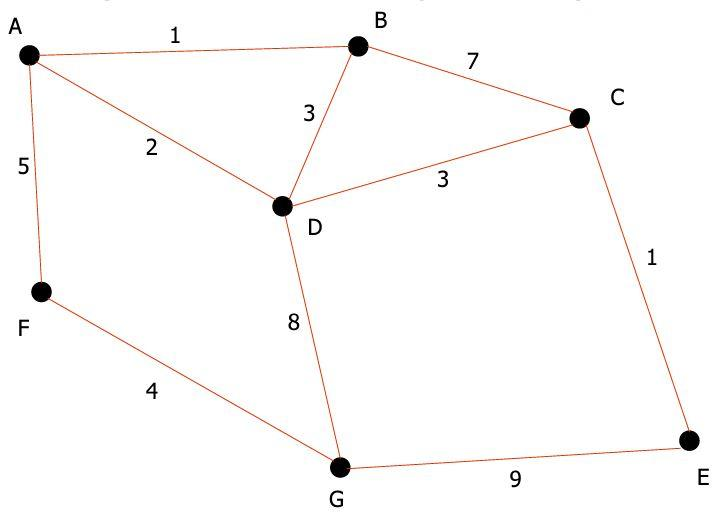


map = [0 1 Inf 2 Inf 5 Inf;
       1 0 7 3 Inf Inf Inf;
       Inf 7 0 3 Inf 1 Inf;
       2 3 3 0 Inf Inf 8;
       Inf 7 1 Inf 0 Inf 9;
       5 Inf Inf Inf Inf 0 4;
       Inf Inf Inf 8 9 4 0];
Nodes = length(map) 

Nodes = 7


distances = ones(1, Nodes)* Inf %starting distances

distances =    Inf   Inf   Inf   Inf   Inf   Inf   Inf



unscanned = zeros(1, Nodes) %unscanned = 0 scanned = 1

unscanned =      0     0     0     0     0     0     0


startNode = 5; %picking starting node
distances(startNode) = 0 %distance to istelf should be zero

distances =    Inf   Inf   Inf   Inf     0   Inf   Inf


while sum(unscanned) < Nodes
    candidates = ones(1, Nodes)* Inf %what we want to explore
    candidates(unscanned == 0) = distances (unscanned == 0) %list of all unscanned nodes
    [currentDist, currentNode] = min(candidates)%pick the current node
    for expNode = 1:Nodes
        newDist = currentDist + map(currentNode,expNode)
        if newDist < distances(expNode)
            distances(expNode) = newDist
        end
    end
    unscanned(currentNode) = 1 %mark the node as visited


end

candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =    Inf   Inf   Inf   Inf     0   Inf   Inf


currentDist = 0

currentNode = 5

newDist = Inf

newDist = 7

distances =    Inf     7   Inf   Inf     0   Inf   Inf


newDist = 1

distances =    Inf     7     1   Inf     0   Inf   Inf


newDist = Inf

newDist = 0

newDist = Inf

newDist = 9

distances =    Inf     7     1   Inf     0   Inf     9


unscanned =      0     0     0     0     1     0     0


candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =    Inf     7     1   Inf   Inf   Inf     9


currentDist = 1

currentNode = 3

newDist = Inf

newDist = 8

newDist = 1

newDist = 4

distances =    Inf     7     1     4     0   Inf     9


newDist = Inf

newDist = 2

distances =    Inf     7     1     4     0     2     9


newDist = Inf

unscanned =      0     0     1     0     1     0     0


candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =    Inf     7   Inf     4   Inf     2     9


currentDist = 2

currentNode = 6

newDist = 7

distances =      7     7     1     4     0     2     9


newDist = Inf

newDist = Inf

newDist = Inf

newDist = Inf

newDist = 2

newDist = 6

distances =      7     7     1     4     0     2     6


unscanned =      0     0     1     0     1     1     0


candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =      7     7   Inf     4   Inf   Inf     6


currentDist = 4

currentNode = 4

newDist = 6

distances =      6     7     1     4     0     2     6


newDist = 7

newDist = 7

newDist = 4

newDist = Inf

newDist = Inf

newDist = 12

unscanned =      0     0     1     1     1     1     0


candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =      6     7   Inf   Inf   Inf   Inf     6


currentDist = 6

currentNode = 1

newDist = 6

newDist = 7

newDist = Inf

newDist = 8

newDist = Inf

newDist = 11

newDist = Inf

unscanned =      1     0     1     1     1     1     0


candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =    Inf     7   Inf   Inf   Inf   Inf     6


currentDist = 6

currentNode = 7

newDist = Inf

newDist = Inf

newDist = Inf

newDist = 14

newDist = 15

newDist = 10

newDist = 6

unscanned =      1     0     1     1     1     1     1


candidates =    Inf   Inf   Inf   Inf   Inf   Inf   Inf


candidates =    Inf     7   Inf   Inf   Inf   Inf   Inf


currentDist = 7

currentNode = 2

newDist = 8

newDist = 7

newDist = 14

newDist = 10

newDist = Inf

newDist = Inf

newDist = Inf

unscanned =      1     1     1     1     1     1     1


distances

distances =      6     7     1     4     0     2     6
